# EEG脑机接口-SVM

## 数据导入

clear;clf;
%load common data
load("ChanName.mat");
load('Pair54.mat');
load('timeRawTrace.mat')
for i = 1:54
    Pair(i) = sprintf("Channel%d & %d",Pair54(i,1),Pair54(i,2));
end

%load personal data
for i = 1:4
    rawTracePerson = sprintf("Person%d\\Person%d\\rawTracePerson%d.mat",i,i,i);
    OSPerson = sprintf("Person%d\\Person%d\\OSPerson%d.mat",i,i,i);

    rawTracePerson_info = whos('-file', rawTracePerson);
    rawTracePerson_name = {rawTracePerson_info.name};
    OSPerson_info = whos('-file',OSPerson);
    OSPerson_name = {OSPerson_info.name};
    
    load(rawTracePerson);
    load(OSPerson);
    for j=1:length(rawTracePerson_name)
        eval(sprintf("%s_P%d = %s;",rawTracePerson_name{j},i,rawTracePerson_name{j}));
    end
  
    for j=1:length(OSPerson_name)
        eval(sprintf("%s_P%d = %s;",OSPerson_name{j},i,OSPerson_name{j}));
    end
    
end

## 观察原始数据

%rawTrace
fs = 300;
t = 0:1/fs:7-(1/fs);
numChannels = 19;
channelNames = [];
channelid = [1:8,10:16,19:20,23:24];

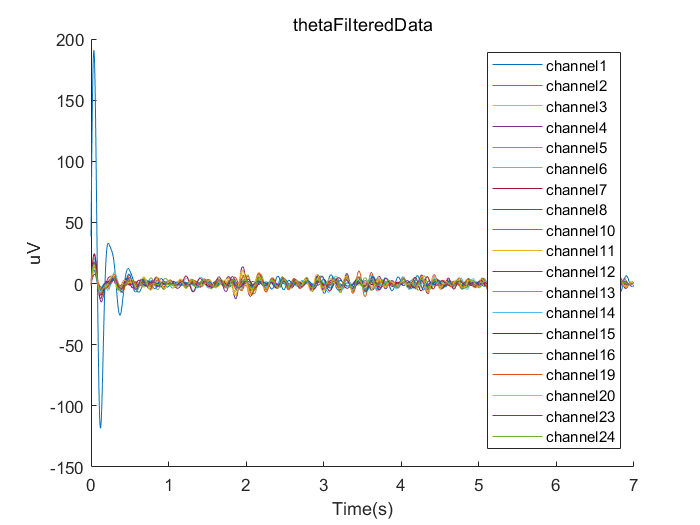

for i = 1:length(channelid)
    channelNames = [channelNames, sprintf("channel%d",channelid(i))];
end
colors = lines(numChannels);
thetaFreqRange = [4 8]; % Theta频带的频率范围（以赫兹为单位）
%bandpass filter
% 计算滤波器参数
filterOrder = 3; % 滤波器阶数
thetaWn = thetaFreqRange / (fs/2); % 归一化的频率范围
% 设计并应用带通滤波器
[b1, a1] = butter(filterOrder, thetaWn, 'bandpass'); % 设计Butterworth带通滤波器
figure;
hold on;
thetaFiltereddata = [];
for i = 1:numChannels
    thetaFilteredData = filtfilt(b1, a1, dataTrial_P1(:,2,i)); % 应用滤波器(零相位滤波）
    plot(t,thetaFilteredData, 'color', colors(i, :));
    thetaFiltereddata = horzcat(thetaFiltereddata,thetaFilteredData);
end
hold off;
legend(channelNames);
title('thetaFilteredData');
xlabel('Time(s)');
ylabel('uV');

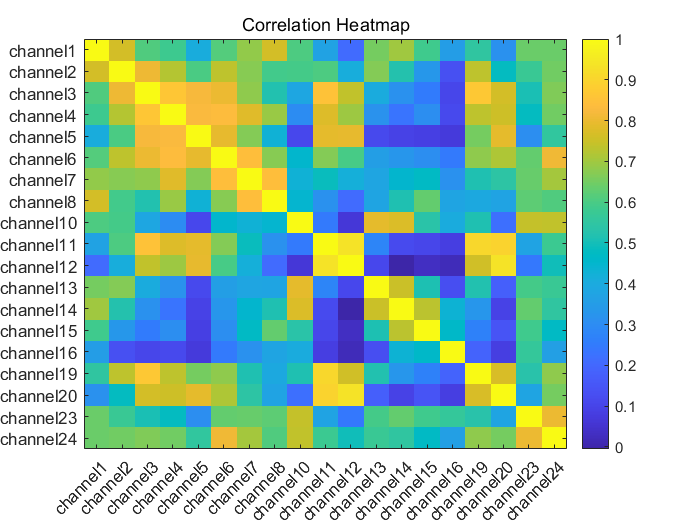

correlationMatrix = corrcoef(thetaFiltereddata);
figure;
imagesc(correlationMatrix);
colorbar; % 添加颜色刻度条
title('Correlation Heatmap'); % 添加标题
xticks(1:numChannels);
yticks(1:numChannels);
xticklabels(channelNames);
yticklabels(channelNames);
xtickangle(45);

## SVM rbf核 分类

### 单人、各组通道配对、全时频点

% 定义范围
lowerBound = 4;
upperBound = 8;
thetaindex = find(fOS_P1>=lowerBound & fOS_P1<= upperBound);
Timeindex = find(Time_P1>=3 & Time_P1<= 7);
% 使用逻辑索引提取满足条件的数据
thetaOS_P1 = OS_P1(Timeindex,thetaindex,:,:);
%将Track替换为match/nonmatch(1/0)
isMatch = (Track_P1<11)';
%PLV值特征提取：
%一、全视频点(TF)
%1：全时频点求常见统计量：平均值、方差、最大值、中值
for j = 1:54
    plv = thetaOS_P1(:,:,:,j);
    featurematrix = statfeature(plv);
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(featurematrix, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = featurematrix(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = featurematrix(cv.test,:);
    y_test = isMatch(cv.test,:);
    
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    
    % 在测试集上进行预测f
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_TF_stat(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end


%2：全时频点奇异值分解
k = 1; % 选择前 k 个奇异值
features = zeros(40, k); % 存储提取的特征
for j = 1:54
    for i = 1:40
        plv = thetaOS_P1(:,:,i,j);
        [U, S, V] = svd(plv);
        features(i,:) = diag(S(1:k, 1:k))';
    end
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(features, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = features(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = features(cv.test,:);
    y_test = isMatch(cv.test,:);
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    
    % 在测试集上进行预测
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_TF_svd(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end


%全时频点PCA
k = 1; % 选择前 k 个主成分
features = zeros(40, k); % 存储提取的特征
[m,n] = size(thetaOS_P1(:,:,1,5));
for j = 1:54
    dataVector = reshape(thetaOS_P1(:,:,:,j), m*n, 40)';
    [coeff, score, ~, ~, explained] = pca(dataVector);
    features = score(:, 1:k);   
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(features, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = features(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = features(cv.test,:);
    y_test = isMatch(cv.test,:);
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    
    % 在测试集上进行预测
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_TF_pca(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end

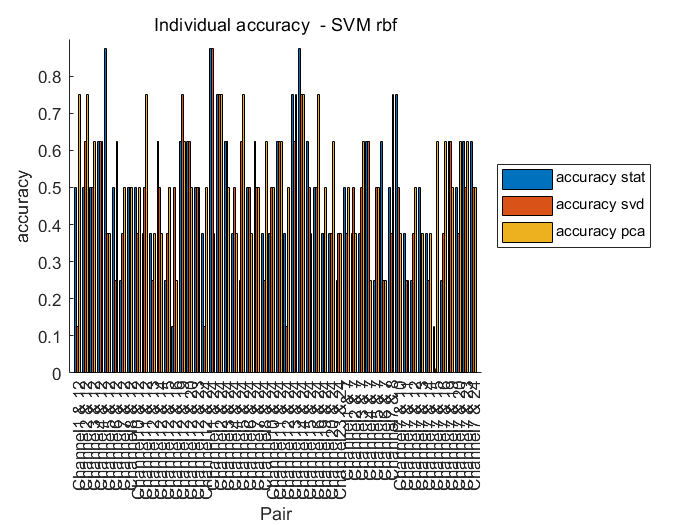

x = 1:54;
% 设置每个柱形的宽度和间隔
barWidth = 0.25;
barSpacing = 0;

% 计算每组数据的偏移位置以使其不重叠显示
offset1 = -(barWidth + barSpacing);
offset2 = 0;
offset3 = barWidth + barSpacing;

% 绘制柱状图
figure;
hold on;
bar(x + offset1, accuracy_TF_stat, barWidth)
bar(x + offset2, accuracy_TF_svd, barWidth)
bar(x + offset3, accuracy_TF_pca, barWidth)
hold off;
title("Individual accuracy  - SVM rbf");
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);
legend(["accuracy_ stat","accuracy_ svd","accuracy_ pca"],'Location', 'eastoutside');

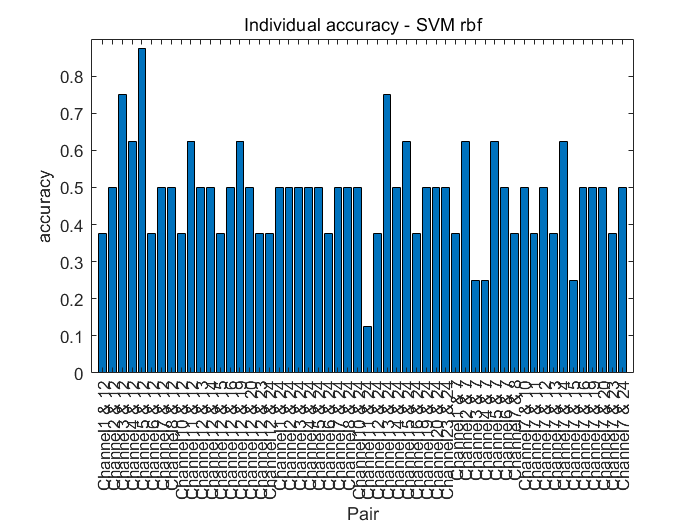

%0：direct
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(freq_OS_P1, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = freq_OS_P1(cv.training,:);
    y_train = isMatch(cv.training,:);
    X_test = freq_OS_P1(cv.test,:);
    y_test = isMatch(cv.test,:);
    % 使用 SVM 建模并进行训练
    svmModel_rbf = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');
    %svmModel_linear = fitcsvm(X_train, y_train, 'KernelFunction', 'linear');
    % 在测试集上进行预测
    y_pred = predict(svmModel_rbf, X_test);
    %y_pred = predict(svmModel_linear, X_test);
    % 评估预测结果
    accuracy_freq_direct(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end
figure;
bar(accuracy_freq_direct);
title("Individual accuracy - SVM rbf");
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

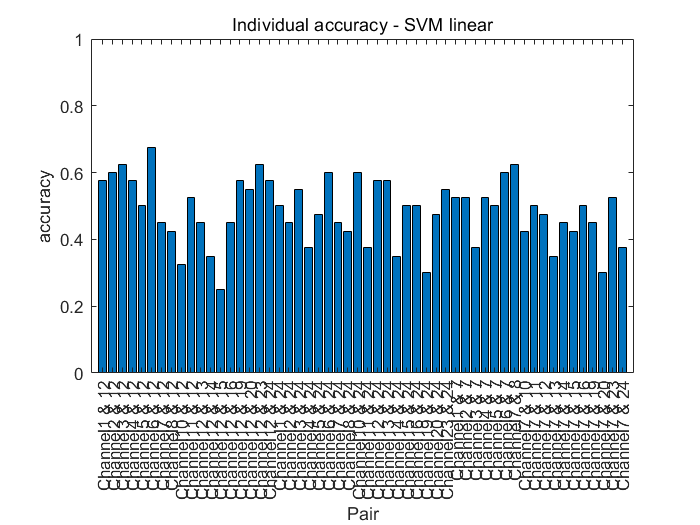

%10折交叉验证
% 定义交叉验证的折数
num_folds = 5;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = freq_OS_P1(train_indices, :);
        train_labels = isMatch(train_indices);
        
        test_data = freq_OS_P1(test_indices, :);
        test_labels = isMatch(test_indices);
        
        % 训练SVM模型
        svm_model = fitcsvm(train_data, train_labels, 'KernelFunction', 'linear');
        
        % 预测测试集的标签
        predicted_labels = predict(svm_model, test_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_freq_direct(j) = mean(accuracies); 
end
figure;
bar(accuracy_freq_direct);
title("Individual accuracy - SVM linear");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

### 全四人同组通道配对

% 定义范围
lowerBound = 4;
upperBound = 8;
for no = 1:4
    % 使用逻辑索引提取满足条件的数据
    eval(sprintf("thetaindex%d = find(fOS_P%d>=lowerBound & fOS_P%d<= upperBound);",no,no,no));
    eval(sprintf("Timeindex%d = find(Time_P%d>=3 & Time_P%d<= 6);",no,no,no))
    eval(sprintf("thetaOS_P%d = OS_P%d(Timeindex%d,thetaindex%d,:,:);",no,no,no,no));
end
%将Track替换为match/nonmatch(1/0)
Track_all = [Track_P1,Track_P2,Track_P3,Track_P4];
isMatch_all = (Track_all<11)';

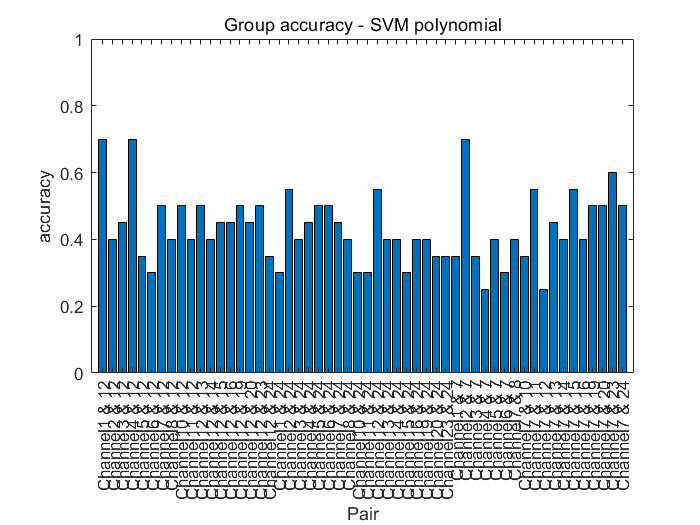


%一、全时频点
%1:常见统计量-polynomial
for j = 1:54
    for no = 1:4
        eval(sprintf("channelPLV_P%d = thetaOS_P%d(:,:,:,j);",no,no));
        eval(sprintf("featurematrix_P%d = statfeature(channelPLV_P%d);",no,no));
    end
    featurematrix = vertcat(featurematrix_P1,featurematrix_P2,featurematrix_P3,featurematrix_P4);
    % 随机划分训练集和测试集
    %rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(featurematrix, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = featurematrix(cv.training,:);
    y_train = isMatch_all(cv.training,:);
    X_test = featurematrix(cv.test,:);
    y_test = isMatch_all(cv.test,:);
    
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'polynomial');
    
    % 在测试集上进行预测f
    y_pred = predict(svmModel, X_test);
    
    % 评估预测结果
    accuracy_TF_stat_all(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end
figure;
bar(accuracy_TF_stat_all);
title("Group accuracy - SVM polynomial");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

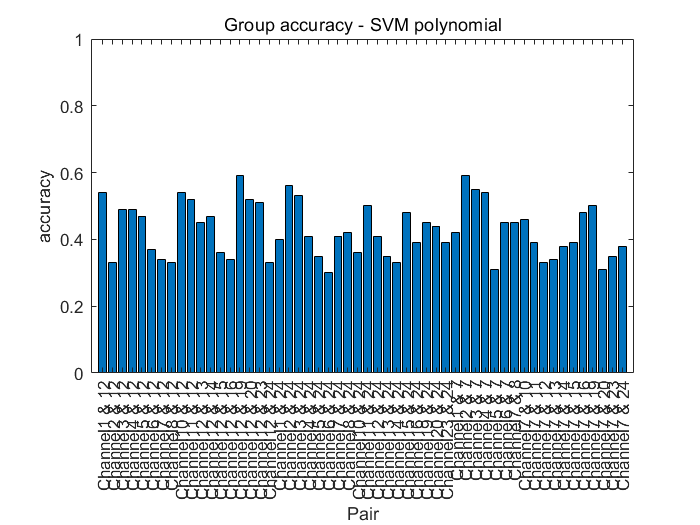

%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
%1:常见统计量-rbf
for j = 1:54
    for no = 1:4
        eval(sprintf("channelPLV_P%d = thetaOS_P%d(:,:,:,j);",no,no));
        eval(sprintf("featurematrix_P%d = statfeature(channelPLV_P%d);",no,no));
    end
    featurematrix = vertcat(featurematrix_P1,featurematrix_P2,featurematrix_P3,featurematrix_P4);
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch_all), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = featurematrix(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = featurematrix(test_indices, :);
        test_labels = isMatch_all(test_indices);
        
        % 训练SVM模型
        svm_model = fitcsvm(train_data, train_labels, 'KernelFunction', 'polynomial');
        
        % 预测测试集的标签
        predicted_labels = predict(svm_model, test_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_TF_stat_all(j) = mean(accuracies); 
end
figure;
bar(accuracy_TF_stat_all);
title("Group accuracy - SVM polynomial");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

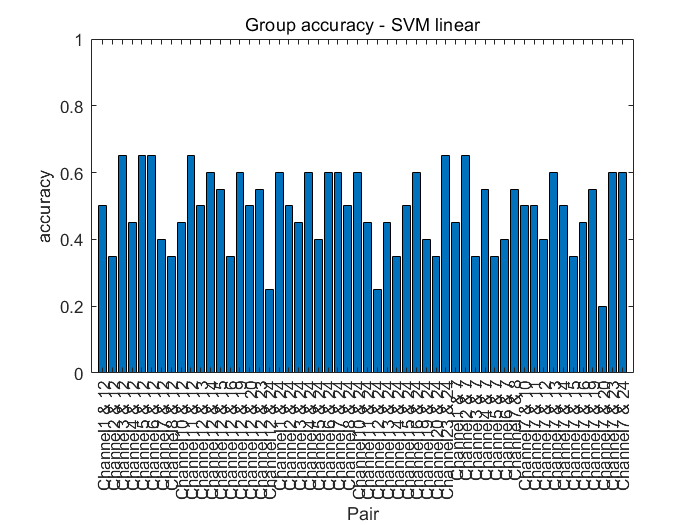

%0:direct 
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    freq_OS_P2 = reshape(thetaOS_P2(:,:,:,j),[],10)';
    freq_OS_P3 = reshape(thetaOS_P3(:,:,:,j),[],40)';
    freq_OS_P4 = reshape(thetaOS_P4(:,:,:,j),[],10)';
    freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
    % 随机划分训练集和测试集
    rng(0);  % 设置随机种子以确保结果可重复
    cv = cvpartition(size(freq_OS, 1), 'Holdout', 0.2);  % 使用 80% 的数据作为训练集，20% 的数据作为测试集
    X_train = freq_OS(cv.training,:);
    y_train = isMatch_all(cv.training,:);
    X_test = freq_OS(cv.test,:);
    y_test = isMatch_all(cv.test,:);
    % 使用 SVM 建模并进行训练
    svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'linear');
    %svmModel = fitcsvm(X_train, y_train, 'KernelFunction', 'rbf');  
    %%rbf核结果全是1
    
    % 在测试集上进行预测
    y_pred = predict(svmModel, X_test);
    % 评估预测结果
    accuracy_freq_direct(j) = sum(y_pred == y_test) / numel(y_test);
    confusionMatrix = confusionmat(y_test, y_pred);
end 
figure;
bar(accuracy_freq_direct);
title("Group accuracy - SVM linear");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

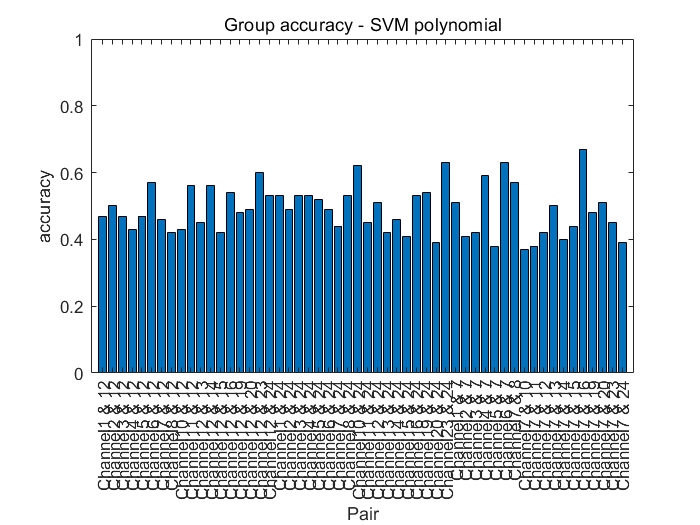

%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
%1:direct 
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    freq_OS_P2 = reshape(thetaOS_P2(:,:,:,j),[],10)';
    freq_OS_P3 = reshape(thetaOS_P3(:,:,:,j),[],40)';
    freq_OS_P4 = reshape(thetaOS_P4(:,:,:,j),[],10)';
    freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch_all), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = freq_OS(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = freq_OS(test_indices, :);
        test_labels = isMatch_all(test_indices);
        
        % 训练SVM模型
        svm_model = fitcsvm(train_data, train_labels, 'KernelFunction', 'polynomial');
        %训练集准确率100%
        % 预测测试集的标签
        predicted_labels = predict(svm_model, test_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_freq_direct(j) = mean(accuracies); 
end 
figure;
bar(accuracy_freq_direct);
title("Group accuracy - SVM polynomial");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

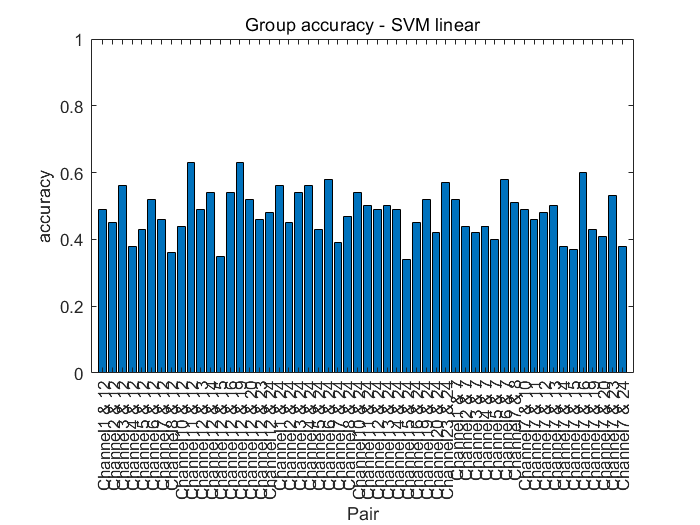

%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
%1:direct 
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    freq_OS_P2 = reshape(thetaOS_P2(:,:,:,j),[],10)';
    freq_OS_P3 = reshape(thetaOS_P3(:,:,:,j),[],40)';
    freq_OS_P4 = reshape(thetaOS_P4(:,:,:,j),[],10)';
    freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch_all), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = freq_OS(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = freq_OS(test_indices, :);
        test_labels = isMatch_all(test_indices);
        
        % 训练SVM模型
        svm_model = fitcsvm(train_data, train_labels, 'KernelFunction', 'linear');
        %训练集准确率越80%
        % 预测测试集的标签
        predicted_labels = predict(svm_model, test_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_freq_direct(j) = mean(accuracies); 
end 
figure;
bar(accuracy_freq_direct);
title("Group accuracy - SVM linear");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

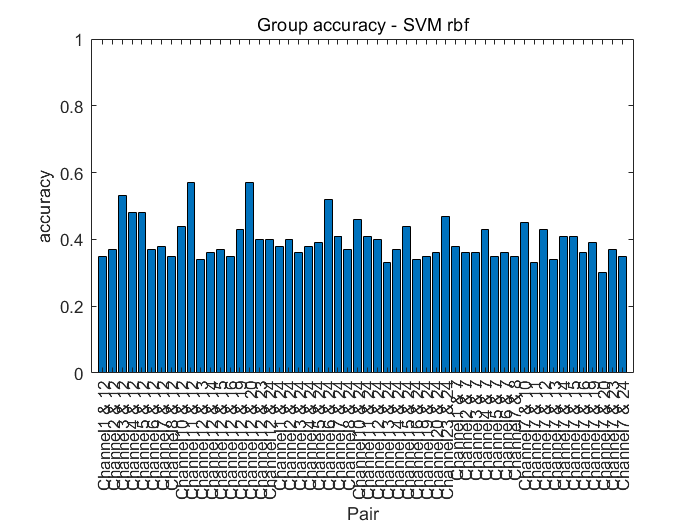

%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
%1:direct 
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    freq_OS_P2 = reshape(thetaOS_P2(:,:,:,j),[],10)';
    freq_OS_P3 = reshape(thetaOS_P3(:,:,:,j),[],40)';
    freq_OS_P4 = reshape(thetaOS_P4(:,:,:,j),[],10)';
    freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch_all), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = freq_OS(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = freq_OS(test_indices, :);
        test_labels = isMatch_all(test_indices);
        
        % 训练SVM模型
        svm_model = fitcsvm(train_data, train_labels, 'KernelFunction', 'rbf');
        %训练集准确率接近100%
        % 预测测试集的标签
        predicted_labels = predict(svm_model, test_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_freq_direct(j) = mean(accuracies); 
end 
figure;
bar(accuracy_freq_direct);
title("Group accuracy - SVM rbf");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

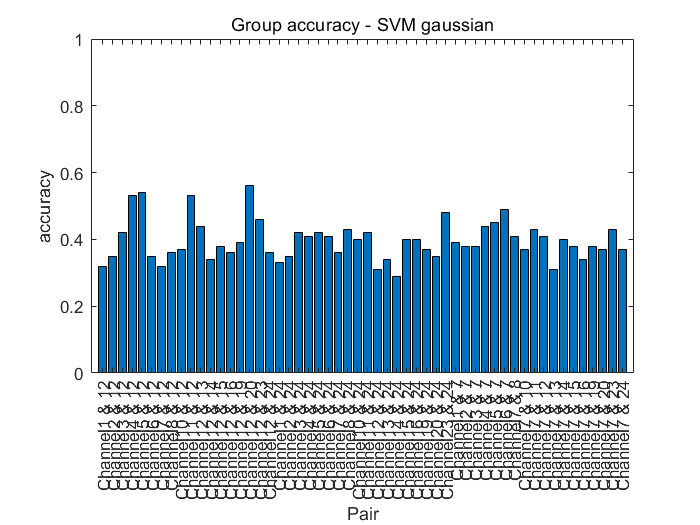

%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
%1:direct 
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    freq_OS_P2 = reshape(thetaOS_P2(:,:,:,j),[],10)';
    freq_OS_P3 = reshape(thetaOS_P3(:,:,:,j),[],40)';
    freq_OS_P4 = reshape(thetaOS_P4(:,:,:,j),[],10)';
    freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch_all), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = freq_OS(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = freq_OS(test_indices, :);
        test_labels = isMatch_all(test_indices);
        
        % 训练SVM模型
        svm_model = fitcsvm(train_data, train_labels, 'KernelFunction', 'gaussian');
        
        % 预测测试集的标签
        predicted_labels = predict(svm_model, test_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_freq_direct(j) = mean(accuracies); 
end 
figure;
bar(accuracy_freq_direct);
title("Group accuracy - SVM gaussian");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);